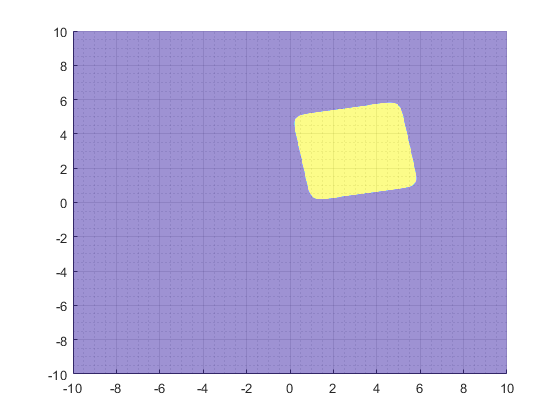

clear;
x1_set = linspace(-10,10,1000);
x2_set = linspace(-10,10,1000);
[x1_grid,x2_grid] = meshgrid(x1_set,x2_set);
sigma_1 = 1;
sigma_2 = 1;
value_grid = nan(size(x1_grid));
p = 1;
for i = 1:numel(x1_grid)
	x1 = x1_grid(i);
	x2 = x2_grid(i);
	R = get_R_z(10/180*pi);
% 	R = R(1:2,1:2);
	distance = norm(diag([2,2,1])*R'*([x1;x2;0]-[3;3;0]),10);
	value = tanh_Substitute(distance,[5,5.1],[10,0],0.99);
	value_grid(i) = value;
end
surf(x1_grid,x2_grid,value_grid,'EdgeColor',"none",'FaceAlpha',0.5);
grid on; grid minor;

clear;
L = 0;
cost_range = 2*[500000,0];
confidence = 0.9;
radius = 10;
safety_distance = 2;
radius_range = [radius,radius+safety_distance];
p = 8;
phi = [0;0;0];
R = get_R(phi);
r1 = 7.5;r2 = 10;r3 = 10;
xb = [-22.5;5;0];
distance1 = diag([radius/r1,radius/r2,radius/r3])*R'*([x(1);x(2);0]-xb);

distance1 = (sum(distance1.^p))^(1/p);
L = L + max([ ...
	tanh_Substitute(distance1,radius_range,cost_range,confidence)]);